data = load('data_603.mat')

data = struct with fields:
    face: [24×21×600 double]


face = data.face;
face_neutral = face(:,:,1:3:end); % extracts the neutral faces 
face_exp = face(:,:,2:3:end); % extracts the expressive faces 
face_illum = face(:,:,3:3:end); % extracts the illuminated faces 
[f1,f2,n] = size(face_neutral); 

Y1 = zeros(n,f1*f2);
Y2 = zeros(n,f1*f2);
for x = 1:n
    aux = face_neutral(:,:,x);
    Y1(x,:) = aux(:)';
    aux = face_exp(:,:,x);
    Y2(x,:) = aux(:)';
end

c1 = n; 
c2 = n; 
Y = [Y1;Y2]; 
F1 = 1:c1; 
F2 = c1+1:c1+c2; 

%apply PCA
[U,Sig,V] = svd(Y','econ');
nPCA = 20; 
Y = Y*U(:,1:nPCA)

Y =    21.5095   -2.7147    0.1685    0.2895   -0.5905    0.9307   -0.4766    1.8083   -0.0094    0.2730   -0.6038    0.8656   -1.3033    0.5839   -0.2078    0.9820   -0.6555    1.7563   -1.3995    0.1507
   21.4678   -1.0568   -0.8435    0.3456   -2.6160    0.5233   -0.0703    2.2542    0.3590   -0.1770    1.0023    0.0643   -1.1876    0.1903    0.6421    0.5525    0.6186    1.0046    1.9264    1.0747
   21.4893   -1.0832   -1.7062    0.4710   -1.9714    0.0935   -0.7183    1.2455   -1.8997    0.7243    0.9479   -0.2536    0.9400    0.0673   -0.6224    0.8383    0.6095    1.4193   -0.4919   -0.6143
   19.0812   -2.5368   -0.1981    3.1762   -6.3091    0.6179   -2.4657   -4.7513    1.4267   -1.9020    1.1178    1.0446    1.4151    1.8680   -0.8857   -1.7045    0.6912    0.2187    0.9385    0.4637
   19.2892   -3.4133    2.3998    1.8487   -5.5850   -3.4576   -0.4345   -3.3325   -0.8783   -3.2638    1.2558    1.5135    0.9411   -0.2016   -2.0132   -1.8895    0.2325   -0.6093   -0.5841  

%splitting the data into test and train for neutral and smiley
Ntrain = 150

Ntrain = 150

Ntest = n - Ntrain; 
training1 = 1:Ntrain; 
training2 = (n+1):(n+Ntrain); 
testing1 = (Ntrain+1):n; 
testing2 =(n+Ntrain+1):(2*n); 
train_idx = [training1,training2]

train_idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


test_idx = [testing1, testing2]; 
Ytrain = Y(train_idx,:);
Ytest = Y(test_idx,:); 

%performing KNN 
knn = 5;  
labels = zeros(length(test_idx),1); 
for z = 1 : length(test_idx)
    ytest = Ytest(z,:); 
    dist_sq = sum((Ytrain - ones(size(Ytrain,1),1)*ytest).^2,2);
    [dsort, isort] = sort(dist_sq, 'ascend'); 
    knear_neb = isort(1:knn); 
    knn_neutral = find(knear_neb <= Ntrain); 
    knn_smile = find(knear_neb > Ntrain); 
    if length (knn_neutral) > length(knn_smile)
        labels(z) = 1; 
    else
        labels(z) = -1; 
    end
end

%Results KNN
sum(labels==1)

ans = 59

%Bayesian decision theory 
P1 = Y(F1,:); 
P2 = Y(F2,:); 
m1 = mean(P1,1); 
m2 = mean(P2,1); 
fprintf('norm(m1-m2) = %d\n', norm(m1 - m2));

norm(m1-m2) = 3.214500e+00


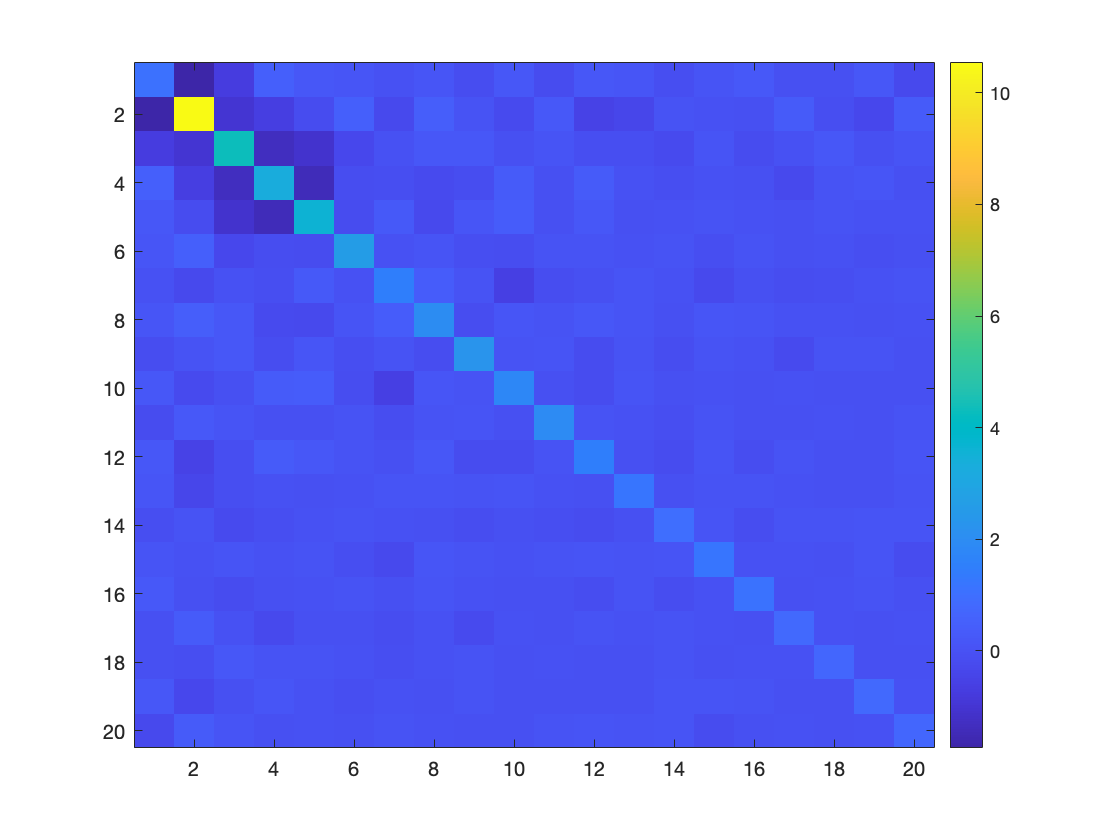

% estimate covariance matrices for each classes and centering the data to
% compute the matrices
P1c = P1 - ones(c1,1)*m1; 
P2c = P2 - ones(c2,1)*m2; 
S1 = P1c'*P1c/c1; 
S2 = P2c'*P2c/c2; 
figure; 
imagesc(S1); 
colorbar; 

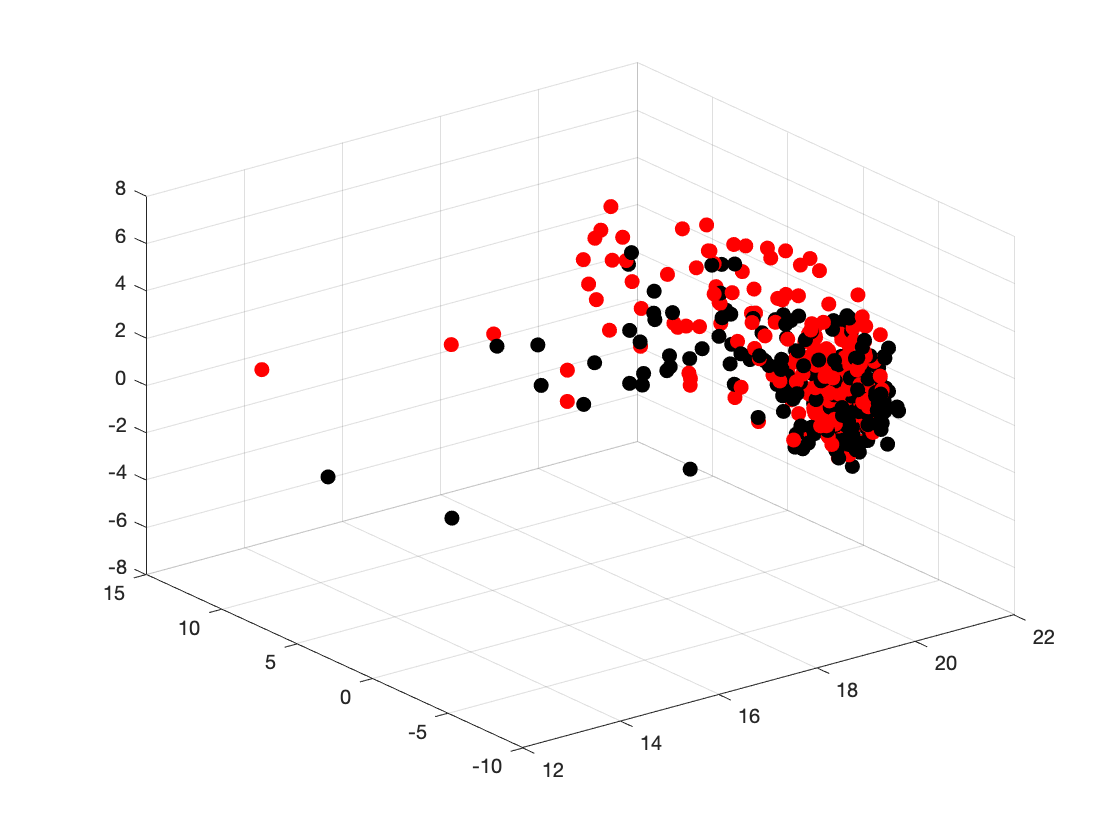

figure; 
hold on; 
grid; 
plot3(Y(F1,1),Y(F1,2),Y(F1,3),'.','Markersize',20,'color', 'k'); 
plot3(Y(F2,1),Y(F2,2),Y(F2,3),'.','Markersize',20,'color', 'r'); 
view(3); 

iS1 = inv(S1);
iS2 = inv(S2);
m1 = m1';
m2 = m2';
w0 = 0.5*(log(det(S2)/det(S1))) - 0.5*(m1'*iS1*m1 - m2'*iS2*m2);
g = @(x)-0.5*x'*(iS1-iS2)*x + x'*(iS1*m1 - iS2*m2) + w0;
% Classify illuminated faces
Y3 = zeros(n,nPCA);
label = zeros(n,1);


for j = 1:n
    aux = face_illum(:,:,j);
    y = (aux(:)'*U(:,1:nPCA))';
    Y3(j,:) = y';
    label(j) = sign(g(y));
end
iplus = find(label > 0);
iminus = find(label < 0);
fprintf('#iplus = %d, #iminus = %d\n',length(iplus),length(iminus));

#iplus = 187, #iminus = 13


## **Performing train test split with varied ratio and neutral and illum**

[g1,g2, i] = size(face_neutral); 
Z1 = zeros(i,g1*g2);
Z2 = zeros(i,g1*g2);
for a = 1:i
    aux = face_neutral(:,:,a);
    Z1(a,:) = aux(:)';
    aux = face_illum(:,:,a);
    Z2(a,:) = aux(:)';
end
d1 = i; 
d2 = i; 
Z = [Z1;Z2]; 
G1 = 1:d1; 
G2 = d1+1:d1+d2; 

%apply PCA
[U,Sig,V] = svd(Z','econ');
nPCAtest2 = 20; 
Z = Z*U(:,1:nPCAtest2)

Z =    21.0080   -4.9801   -1.1539    0.0521   -0.1114    0.7211   -1.0592    1.8351   -1.1631    0.6658   -0.2494    0.8744   -0.4777    0.7957   -0.1987    0.8172   -0.7683    0.2056   -1.6628    0.5226
   21.2437   -3.4138    0.2567   -1.1740   -1.4566    0.4681   -0.6294    1.2476   -1.4173    0.6497    0.5586    0.3792   -0.7330    2.0249    0.3342    1.8744   -0.5635    0.5731    0.7659   -1.0977
   21.2666   -3.5020    0.4199    0.0862   -1.9448    0.1312   -2.4878    0.4984    0.0129    0.6253    1.0698    0.4603   -0.1358    1.0339    0.5620   -0.5643   -1.0811   -0.9764   -0.1922   -0.4861
   18.4642   -6.7122   -0.3558   -5.9307   -5.1194    1.5713    1.1495   -3.4423    1.0286   -1.1580    0.3527   -0.8177   -0.0677    0.2984   -1.8085   -0.6540   -0.2644   -0.3583    0.6148    0.8975
   18.9649   -5.0358   -2.9587   -6.5014   -3.3107   -1.7629    2.0505   -0.1241    2.3433   -0.8981    1.8589    0.0733    1.0933   -1.4481   -1.1182   -1.3037    0.2784   -1.2569   -0.6454  

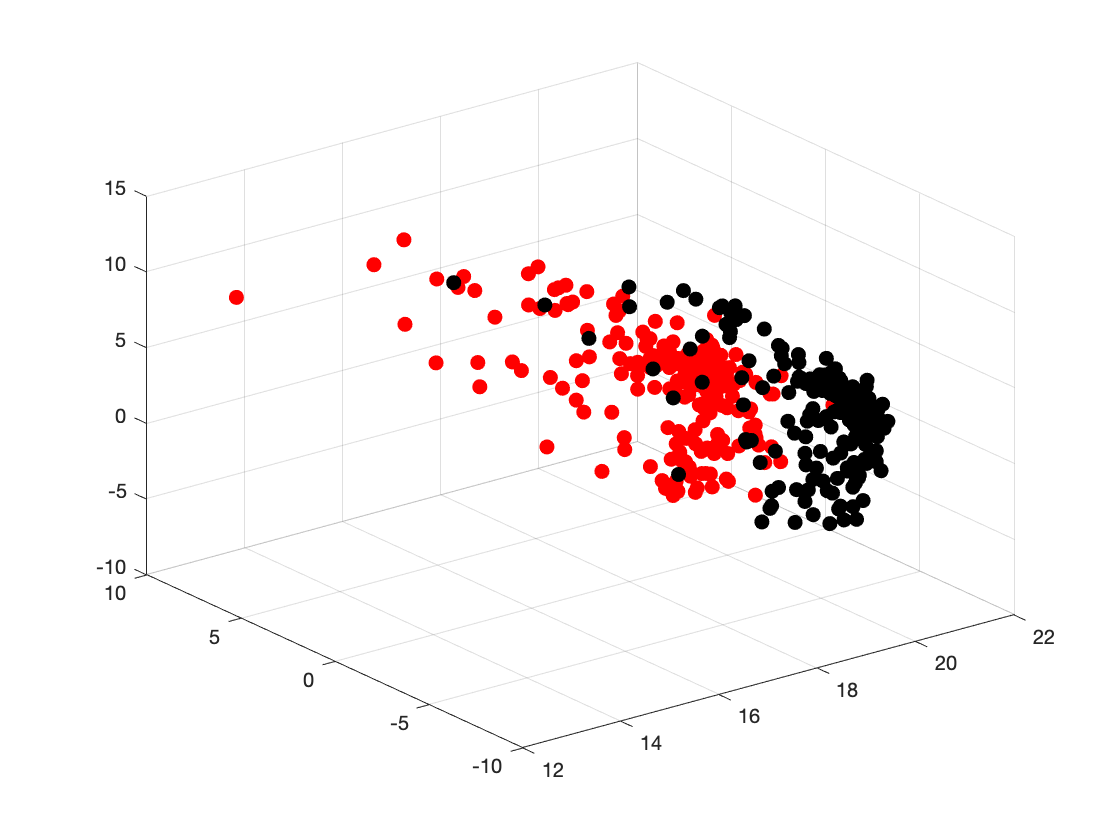

figure; 
hold on; 
grid; 
plot3(Z(G1,1),Z(G1,2),Z(G1,3),'.','Markersize',20,'color', 'k'); 
plot3(Z(G2,1),Z(G2,2),Z(G2,3),'.','Markersize',20,'color', 'r'); 
view(3);

%test train split with neutral and illum N = 150
Ltrain = 100

Ltrain = 100

Ltest = a - Ltrain; 
training2 = 1:Ltrain; 
training3 = (a+1):(a+Ltrain); 
testing4 = (Ltrain+1):a; 
testing5 =(a+Ltrain+1):(2*a); 
train2_idx = [training2,training3]

train2_idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


test3_idx = [testing4, testing5]; 
Ztrain = Z(train2_idx,:);
Ztest = Z(test3_idx,:); 

%Results KNN
sum(labels==1)

ans = 59

%Bayesian decision theory 
B1 = Z(G1,:); 
B2 = Z(G2,:); 
mu1 = mean(B1,1); 
mu2 = mean(B2,1); 
fprintf('norm(mu1-mu2) = %d\n', norm(mu1 - mu2));

norm(mu1-mu2) = 7.495824e+00


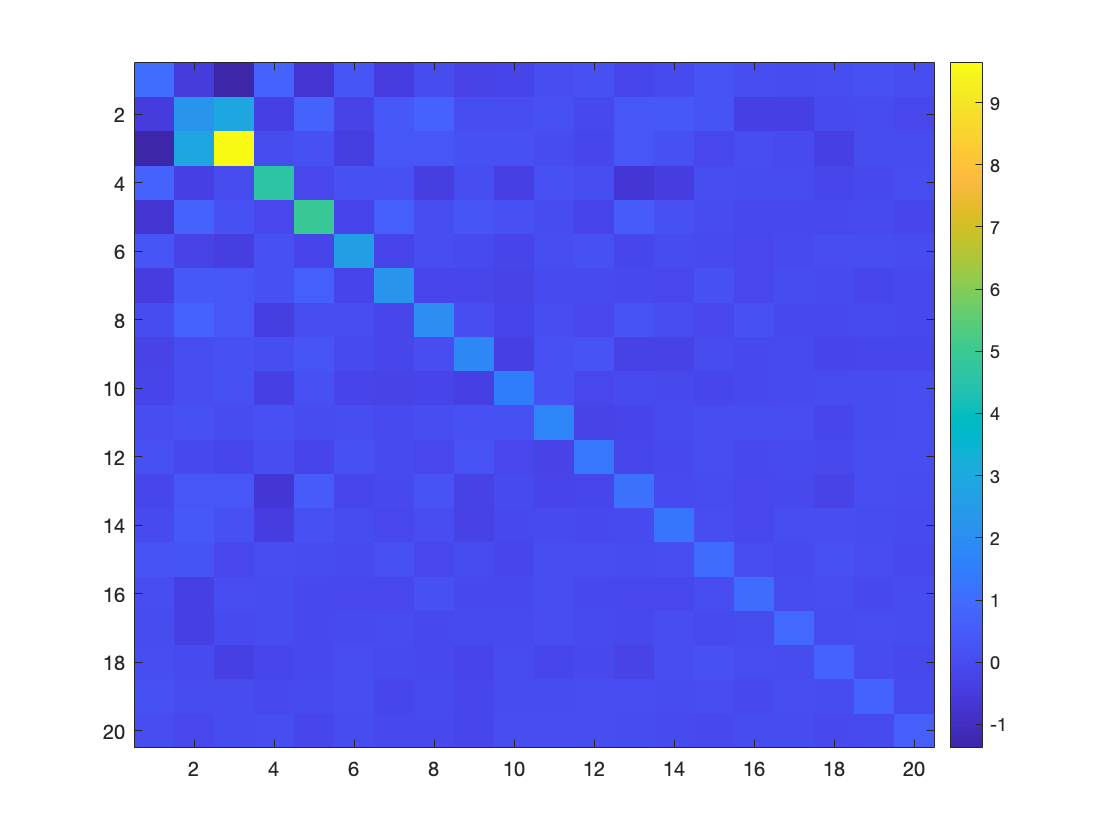

% estimate covariance matrices for each classes and centering the data to
% compute the matrices
B1c = B1 - ones(d1,1)*mu1; 
B2c = B2 - ones(d2,1)*mu2; 
S1test2 = B1c'*B1c/d1; 
S2test2 = B2c'*B2c/d2; 
figure; 
imagesc(S1test2); 
colorbar; 

iS1test2 = inv(S1test2);
iS2test2 = inv(S2test2);
mu1 = mu1';
mu2 = mu2';
w1 = 0.5*(log(det(S2test2)/det(S1test2))) - 0.5*(mu1'*iS1test2*mu1 - mu2'*iS2test2*mu2);
q = @(a)-0.5*a'*(iS1test2-iS2test2)*a + a'*(iS1test2*mu1 - iS2test2*mu2) + w1;
% Classify illuminated faces
Y4 = zeros(i,nPCAtest2);
labeltest2 = zeros(i,1);


for w = 1:i
    auxtest2 = face_exp(:,:,i);
    r = (auxtest2(:)'*U(:,1:nPCAtest2))';
    Y4(w,:) = r';
    labeltest2(w) = sign(q(r));
end
iplustest2 = find(labeltest2 > 0);
iminustest2 = find(labeltest2 < 0);
fprintf('#iplustest2 = %d, #iminustest2 = %d\n',length(iplustest2),length(iminustest2)); 

#iplustest2 = 200, #iminustest2 = 0


Pose Dataset Experiment

load('pose.mat');

%Restructuring data:

[p1,p2,poses,subjects]=size(pose)

p1 = 48

p2 = 40

poses = 13

subjects = 68


k = 68; %number of subjects to use for classification

pose_trainX = zeros(10*k,p1*p2);
pose_trainY = zeros(10*k,1);
pose_testX = zeros(3*k,p1*p2);
pose_testY = zeros(3*k,1);

for i = 1:k
    for j = 1:10
        temp = pose(:,:,j,i);
        idx = (i-1)*10+j;
        pose_trainX(idx,:) = temp(:); 
        pose_trainY(idx)=i;
    end
    
    for j = 11:13
        temp = pose(:,:,j,i);
        idx = (i-1)*3+(j-10);
        pose_testX(idx,:) = temp(:); 
        pose_testY(idx)=i;
    end
    
end
%now pose: rows = image, cols = pixel data

d=5;

%[pose_trainX2,V,mu_trainP] = myPCA(pose_trainX,d);

%calibrating PCA using training data:
train_nP = size(pose_trainX,1);
mu_trainP = mean(pose_trainX,1);
pose_trainX_center = pose_trainX-repmat(mu_trainP,[train_nP,1]);
[U,S,V] = svd(pose_trainX_center);

%applying PCA to training data
pose_trainX2 = pose_trainX_center*V(:,1:d);

%applying PCA to test data
test_nP = size(pose_testX,1);
pose_testX2 = (pose_testX-repmat(mu_trainP,[test_nP,1]))*V(:,1:d); 


%Bayesian classifier:

%Training:

% currently deprecated in case each class has different sizes
% %restructuring training data for looping:
% train_xs = zeros(10,d,k); %row = pose, column = pixel, 3d: subject/class
% for i=1:k
%     train_xs(:,:,i) = pose_trainX2(pose_trainY==i,:);
% end

P = repmat(1/k,[k,1]); %applying equal prior probability to each class

%computing sample mean and covariance for each class:
train_mus = zeros(d,k);
train_vars = zeros(d,d,k);
train_Ws = zeros(d,d,k);
train_ws = zeros(d,k);
train_omegas = zeros(k,1);


for i=1:k

    temp_X = pose_trainX2(pose_trainY==i,:);
    temp_N = size(temp_X,1);
    temp_mu = mean(temp_X,1);
    temp_X_demean = temp_X-repmat(temp_mu,[temp_N,1]); %demeaned face_n to compute covariance matrix
    temp_var = temp_X_demean'*temp_X_demean/temp_N;
    
    train_mus(:,i) = temp_mu;
    train_vars(:,:,i) = temp_var;
   
    temp_invar = inv(temp_var);
    train_Ws(:,:,i) = -0.5*temp_invar;
    train_ws(:,i) = temp_invar*temp_mu';
    train_omegas(i) = -0.5*temp_mu*temp_invar*temp_mu'-0.5*log(det(temp_var))+log(P(i));
end



%computing and storing discriminant function values
G_pose = zeros(test_nP,k);
gp = @(x,a) x*train_Ws(:,:,a)*x'+train_ws(:,a)'*x'+train_omegas(a) %defining discriminant function, with x = obs. row, a = class

gp = function_handle with value:
    @(x,a)x*train_Ws(:,:,a)*x'+train_ws(:,a)'*x'+train_omegas(a)



for i = 1:test_nP
    for j = 1:k
        G_pose(i,j) = gp(pose_testX2(i,:),j);
    end
end

%making predictions
G_pose;
[Z,pose_testY_prB]=max(G_pose,[],2);
pose_Bcorrect = (pose_testY_prB==pose_testY);
mean(pose_Bcorrect)

ans = 0.2255

%kNN
K = 20;
l=1;
pose_testY_prK = myKNN(pose_trainX2,pose_trainY,pose_testX2,K,l);

pose_Kcorrect = (pose_testY_prK==pose_testY);
mean(pose_Kcorrect)

ans = 0.0882